clc;
clear;
close all;

%% Problem Definition

CostFunction = @(x) MOPn(x);      % Cost Function

nVar = 10;             % Number of Decision Variables

VarSize = [1 nVar];   % Size of Decision Variables Matrix

VarMin = -5;          % Lower Bound of Variables
VarMax = 5;          % Upper Bound of Variables

% Number of Objective Functions
nObj = numel(CostFunction(unifrnd(VarMin, VarMax, VarSize)));


%% NSGA-II Parameters

MaxIt = 100;      % Maximum Number of Iterations

nPop = 50;        % Population Size

pCrossover = 0.7;                         % Crossover Percentage
nCrossover = 2*round(pCrossover*nPop/2);  % Number of Parnets (Offsprings)

pMutation = 0.4;                          % Mutation Percentage
nMutation = round(pMutation*nPop);        % Number of Mutants

mu = 0.02;                    % Mutation Rate

sigma = 0.1*(VarMax-VarMin);  % Mutation Step Size


% 设置非默认求解器选项
options = optimoptions("gamultiobj","PopulationSize",50,"ParetoFraction",0.1,...
    "Display","diagnose","PlotFcn",["gaplotdistance","gaplotpareto",...
    "gaplotspread"]);

% 求解
[solution,objectiveValue] = gamultiobj(@MOP2,nVar,[],[],[],[],repmat(-5,nVar,...
    1),repmat(5,nVar,1),[],[],options);


Diagnostic information:
Multi-objective function: @MOP2
10 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible
PopulationSize:    50
ParetoFraction:    0.1
Display:           'diagnose'
PlotFcns:          {  'gaplotdistance' 'gaplotpareto' 'gaplotspread' }
End of diagnostic information.


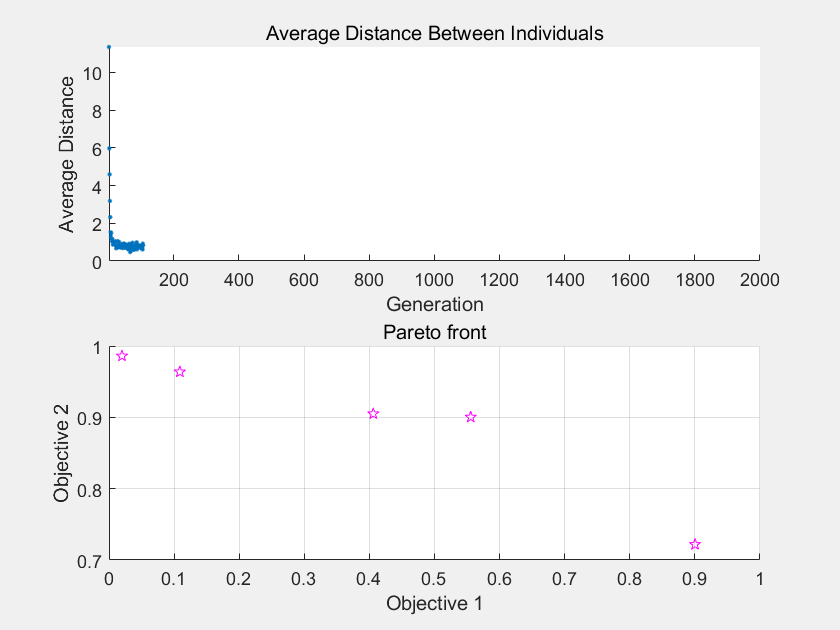


% 清除变量
clearvars options